# 10 Least-Squares Problems 

#### Example

The following table contains the homework and final grades of 30 students.

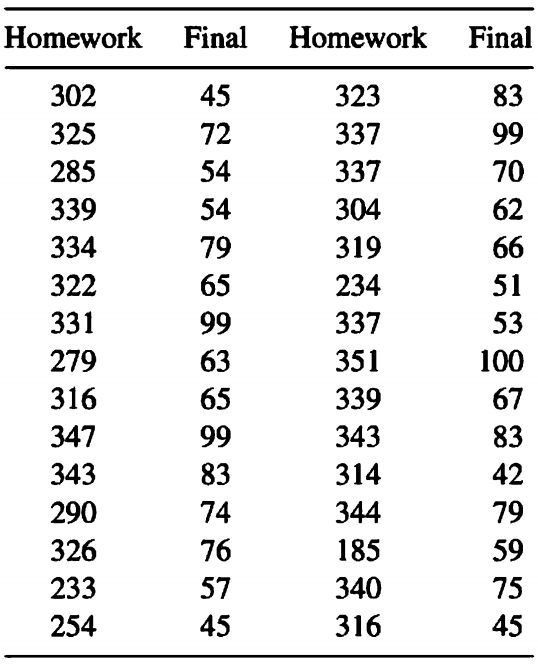

Based on these data, what is the homeowrk grade that gives a predition of A+ (95%) in the final?

HW  = [302 325 285 339 334 322 331 279 316 347 343 290 326 233 254 ... 
       323 337 337 304 319 234 337 351 339 343 314 344 185 340 316   ];
FIN = [45 72 54 54 79 65 99 63 65 99 83 74 76 57 45 83 99 70 62 66 51 53 ... 
       100 67 83 42 79 59 75 45];


## 10.2 LINEAR LEAST-SQUARES PROBLEMS   

- A linear least-squares problem is 


$$\min_{x\in \mathbb{R}^n} f(x)=1/2||Jx-y||^2.$$


- The gradient is $\nabla f = J^T(Jx-y)$

- The Hessian is $\nabla^2 f =  J^TJ$

- The function $f$ is convex (why?)

- If $x^*$ is such that $\nabla f(x^*)=0$, then $x^*$ is a global minimizer of $f$ and we have the norm equations  $J^TJx = Jy$

- We assum that $m\ge n$ where $m$ is the number of observations. That is $m$ is the numebr of rows in $J$.

-  We assume also that $J$ has a full (column) rank.

- We solve Linear Least Square by QR method or by SVD method

Let $J=QR$

rng('default')
J = randi([-3,3],10,3);
[Q, R]= qr(J)

Q =    -0.2520    0.3951   -0.1499   -0.6887   -0.1519    0.1205    0.0589    0.2068   -0.4304   -0.1205
   -0.3780   -0.2657    0.3205    0.1394   -0.1293    0.4665    0.2687   -0.3321   -0.1733   -0.4665
    0.3780   -0.5927   -0.4034   -0.2417   -0.3351    0.0260   -0.1896   -0.2624   -0.2573   -0.0260
   -0.3780    0.1635   -0.6253    0.5757   -0.1705   -0.0079   -0.0833    0.0515   -0.2630    0.0079
   -0.1260   -0.2316   -0.2959   -0.1286    0.8894    0.0775   -0.0026   -0.0711   -0.1352   -0.0775
    0.3780    0.2657   -0.1410    0.0808    0.0501    0.8395   -0.1014    0.0437    0.1220    0.1605
    0.2520    0.0341   -0.2574    0.0171   -0.0203   -0.0734    0.9254   -0.0199    0.0292    0.0734
         0   -0.4292    0.0483    0.0841   -0.0404    0.1298    0.0671    0.8751   -0.0288   -0.1298
   -0.3780   -0.1226   -0.3538   -0.2818   -0.1438    0.0915    0.0007   -0.0219    0.7744   -0.0915
   -0.3780   -0.2657    0.1410   -0.0808   -0.0501    0.1605    0.1014   -0.0437   -0.1

R =    -7.9373   -3.0237    2.0158
         0   -6.9898    1.7032
         0         0   -5.5710
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
